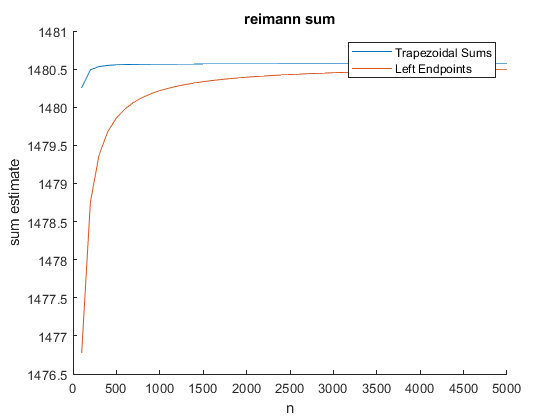

%comparison of trapezoidal reimann sums and left endpoint reimann sums
counter = 1;
c = 100:100:5000;
leftsums = NaN(length(c),1);
trapsums = NaN(length(c),1);
for n = c
    trapsums(counter) = trapsolver(n);
    leftsums(counter) = leftsolver(n);
    counter = counter+1;
end

hold on
plot(c,trapsums,'DisplayName','Trapezoidal Sums')
plot(c,leftsums,'DisplayName','Left Endpoints')
legend('show')
xlabel('n')
ylabel('sum estimate')
title('reimann sum')

function y = leftsolver(n)
    dx = 30/n;
    leftends = 0:dx:30-dx;
    f = @(x)200*x/(5+x)*exp(-2*x/30);
    areas = arrayfun(f,leftends)*dx;
    y = sum(areas);
end

function y = trapsolver(n)
    dx = 30/n;
    leftends = 0:dx:30-dx;
    rightends = 0+dx:dx:30;
    
    f = @(x)200*x/(5+x)*exp(-2*x/30);
    areas = (arrayfun(f,leftends)+arrayfun(f,rightends))/2*dx;
    
    y = sum(areas);
end